run AircraftData.mlx

Vanguard = struct with fields:
              MTOW: 142740
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 142740
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]



S = Vanguard.Wing.S;
Taper = Vanguard.Wing.TaperRatio;
b = Vanguard.Wing.b;
Yehudi = Vanguard.Wing.Yehudi;
yF = Vanguard.Fuselage.Diameter/2;

Cr = Vanguard.Wing.Cr

Cr = 16.1291

Ct = Cr*Taper

Ct = 6.4516

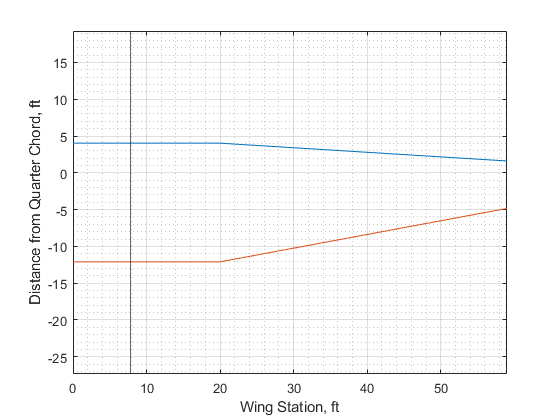


C = zeros(1,b/2);
Y = zeros(1,b/2);

C(1) = Cr;
Y(1) = 0;

for y=2:1:b/2
    
    Y(y) = y;
    
    if y<=Yehudi
        
        C(y) = Cr;
        
    else
        
        C(y) = Cr*(1-(1-Taper)*2*((y-Yehudi)/(b-2*Yehudi)));
        
    end
    
    
end

LE = C*0.25;

TE = -C*0.75;
plot (Y,LE)
hold on
plot (Y,TE)
xline(yF)
hold off
axis equal
xlabel("Wing Station, ft");
ylabel("Distance from Quarter Chord, ft");
grid on
grid minor